clear all
clc

**Loading Dats**

load array_prices.mat;
load myPrice_dt.mat;

**Selection of a subset of Dates**

Ret = tick2ret(prices_val);
numAssets = size(Ret, 2);
CovMatrix = cov(Ret);

**Building the views**

tau = 1 / length(Ret);
v = 3; %total 3 views v = num views
P = zeros(v, numAssets);
q = zeros(v,1);
Omega = zeros(v);

**View 1:  5% annual return of Apple**

P(1, assetNames == 'AAPLUSEquity') = 1;
q(1) = 0.05;

**View 2: 3% annual return of Amazon**

P(2, assetNames == 'AMZNUSEquity') = 1;
q(2) = 0.03;

**View 3: Google is going to outperform JPMorgan by 5%**

P(3, assetNames == 'GOOGLUSEquity') = 1;
P(3, assetNames == 'JPMUSEquity') = -1;
q(3) = 0.05;

Omega(1,1) = tau.*P(1,:)*CovMatrix*P(1,:)';
Omega(2,2) = tau.*P(2,:)*CovMatrix*P(2,:)';
Omega(3,3) = tau.*P(3,:)*CovMatrix*P(3,:)';

**From annual view to daily view**

bizyear2bizday = 1/252;
q = q * bizyear2bizday;
Omega = Omega*bizyear2bizday;

**Plot views distributions**

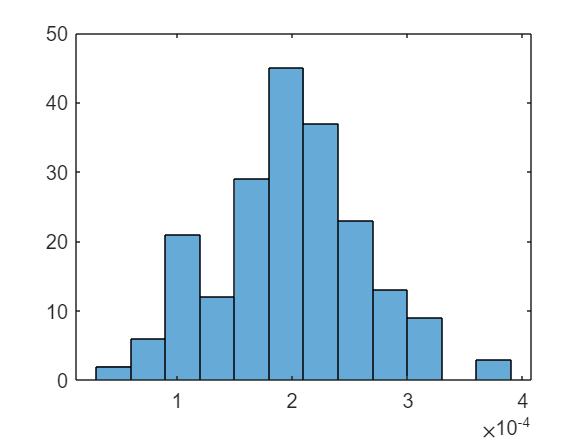

X_views = mvnrnd(q, Omega, 200);
histogram(X_views(:,1))

**Market implied return**

load("cap.mat");
wMkt = cap(1:15)/sum(cap(1:15));
lambda = 1.2;
mu_mkt = lambda.*CovMatrix*wMkt;
C = tau.*CovMatrix; %confidence matrix

**Plot prior distribution**

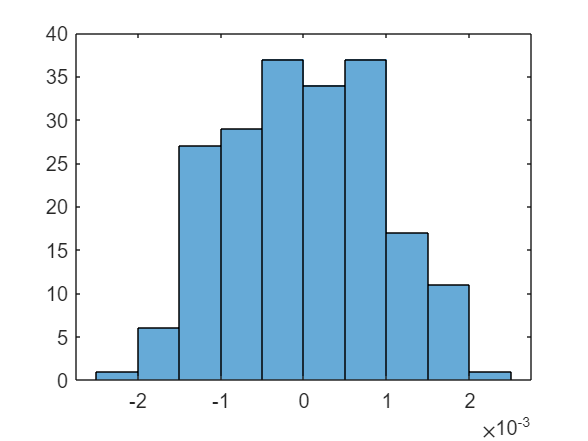

X = mvnrnd(mu_mkt, C, 200);
histogram(X(:,1))

**Black Litterman **

muBL = inv(inv(C)*P'*inv(Omega)*P)*(P'*inv(Omega)*q+inv(C)*mu_mkt);

covBL = inv(P'*inv(Omega)*P + inv(C));

table(assetNames', mu_mkt*252, muBL*252, 'VariableNames', ["Asset Names", "Prior Belief Market Return", "Updated view of Market Return"])

ans = 15×3 table
      Asset Names      Prior Belief Market Return    Updated view of Market Return
    _______________    __________________________    _____________________________

    "AAPLUSEquity"              0.024917                          NaN             
    "JNJUSEquity"              0.0065693                          NaN             
    "AMZNUSEquity"               0.01995                          NaN             
    "MCDUSEquity"               0.014567                          NaN             
    "JPMUSEquity"               0.020688                          NaN             
    "KOUSEquity"                0.011599                          NaN             
    "GOOGLUSEquity"             0.024523                          NaN             
    "FUSEquity"                  0.03851                          NaN             
    "NKEUSEquity"               0.021144          

**Plot Distiribution**

XBL = mvnrnd(muBL, covBL, 200);
histogram(XBL)

**Portfolio Optimization**

port = Portfolio('NumAssets', numAssets, 'Name', 'MeanVariance');
port = setDefaultConstraints(port);
Port = setAssetMoments(port, mean(Ret), CovMatrix);
pwgt = estimateFrontier(Port, 100);
[pf_vola, pf_ret] = estimatePortMoments(Port, pwgt);

**Max Sharpe**

N = 100;
ExpRet = mean(Ret);
rf = 0;
SharpeArray = ones(1,n);
for i = 1:n
    s = getSharpeRatio(pwgt(:,i), ExpRet, CovMatrix, rf);
    SharpeArray(i) = s;
end
[MaxSharpe, index_] = max(SharpeArray);
wts = estimateMaxSharpeRatio(Port);

**Plot Sharp vs Vola**

plot(pf_vola, SharpeArray, '-o', 'LineWidth',3)
hold on
scatter(pf_vola(index_), MaxSharpe, 'LineWidth', 4)
xlabel('Volatility')
ylabel('SharpeRatio')

**Black Litterman Portfolio**

portBL = Portfolio('NumAssets', numAssets, 'Name', 'MV with BL');
portBL = setAssetMoments(portBL, muBL, CovMatrix*covBL);
portBL = setDefaultConstraints(portBL);
wtsBL = estimaeteMaxSharpRatio(Port);
a = pwgt(:,44);

**Plot**

ax1 = subplot(1,2,1);
idx = wts>0.001;
pie(ax1, wts(idx), assetNames(idx));
title(ax1, port.Name, 'Position', [-0.05, 1.6, 0]);

ax2 = subplot(1,2,2);
idx_BL = wtsBL > 0.001;
pie(ax2, wtsBL(idx_BL), assetNames(idx_BL));
title(ax2, portBL.Name, 'Position', [-0.05, 1.6, 0]);